# Calibrating hyperelastic materials

This reading is to develop a method for calibrating different hyperelastic materials using a set of stress-stretch data. The experimental data are collected from [this work](https://doi.org/10.1016/j.actbio.2019.10.020). Note, incompressibility of the materials is assumed.

clear; clc; close all;

Let's load the CSV data files.

data_dir= 'dataset';
csvfiles= dir(fullfile(data_dir, '*.csv'));
s_b     = importfile(fullfile(data_dir, csvfiles(1).name)); % Equibiaxial
s_x     = importfile(fullfile(data_dir, csvfiles(2).name)); % Off-biaxial X
s_y     = importfile(fullfile(data_dir, csvfiles(3).name)); % Off-biaxial Y

Data preparation for equibiaxial dataset:

% DATA for all sets
sb_data_11  = table2array(s_b(:,["Lambda11","Sigma11MPa"]));
sb_data_22  = table2array(s_b(:,["Lambda22","Sigma22MPa"]));
sx_data_11  = table2array(s_x(:,["Lambda11","Sigma11MPa"]));
sx_data_22  = table2array(s_x(:,["Lambda22","Sigma22MPa"]));
sy_data_11  = table2array(s_y(:,["Lambda11","Sigma11MPa"]));
sy_data_22  = table2array(s_y(:,["Lambda22","Sigma22MPa"]));

sb_data_11 = data_corr(sb_data_11);
sb_data_22 = data_corr(sb_data_22);
sx_data_11 = data_corr(sx_data_11);
sx_data_22 = data_corr(sx_data_22);
sy_data_11 = data_corr(sy_data_11);
sy_data_22 = data_corr(sy_data_22);

ss_data_11 = [sb_data_11; sx_data_11; sy_data_11];
ss_data_22 = [sb_data_22; sx_data_22; sy_data_22];

sb_lam    = [sb_data_11(:,1) sb_data_22(:,1)];
sx_lam    = [sx_data_11(:,1) sx_data_22(:,1)];
sy_lam    = [sy_data_11(:,1) sy_data_22(:,1)];

### The case for Gasser-Ogden-Holzapfel (GOH) model

#### All 3 sets of data

Optimization

% c: C10, k1, k2, kappa, [theta(degree)]
c0  = [0, 0, 0, 0, [85,105]];
CF = 1;
[optC_GS, fval, W_func]  = W_calibrator([ss_data_11 ss_data_22], c0, CF);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Responses

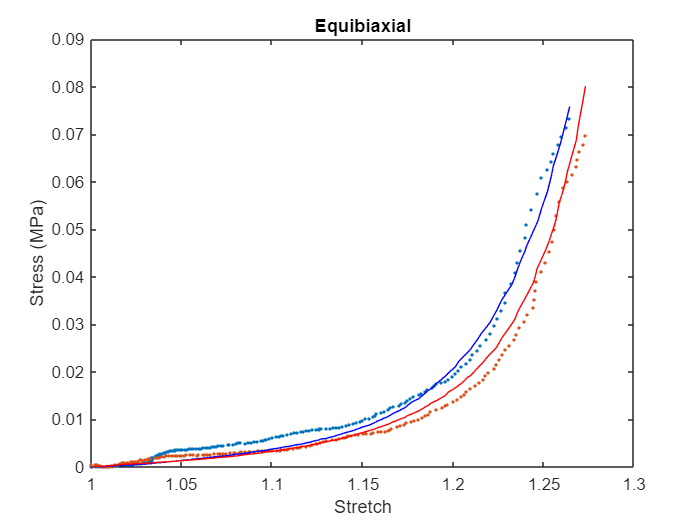

sb_GOH_GS = W_func(sb_lam, optC_GS);
ss_plot([sb_data_11 sb_data_22],"Equibiaxial")
hold on;
plot(sb_lam(:,1),sb_GOH_GS(:,1),'b-')
plot(sb_lam(:,2),sb_GOH_GS(:,2),'r-')
hold off

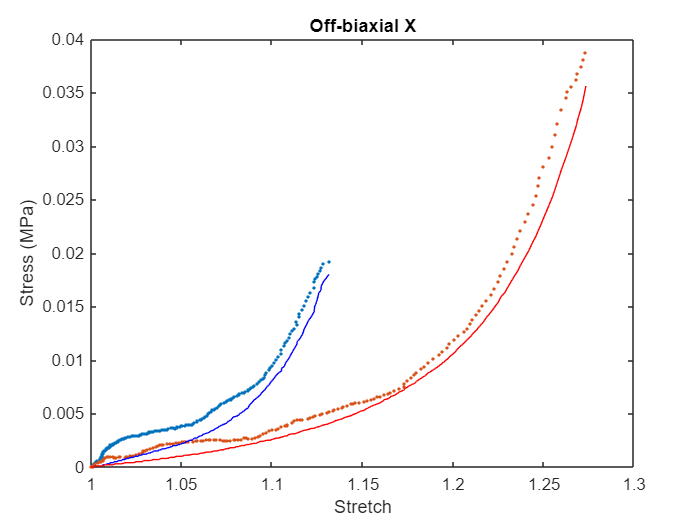


sx_GOH_GS = W_func(sx_lam, optC_GS);
ss_plot([sx_data_11 sx_data_22],"Off-biaxial X")
hold on;
plot(sx_lam(:,1),sx_GOH_GS(:,1),'b-')
plot(sx_lam(:,2),sx_GOH_GS(:,2),'r-')
hold off

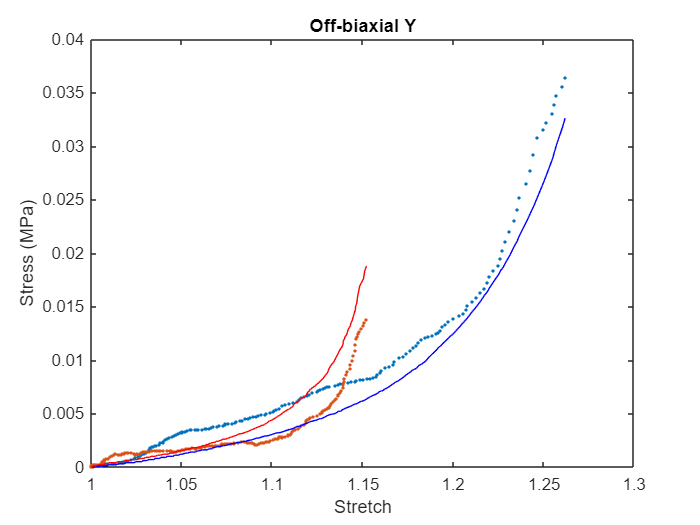


sy_GOH_GS = W_func(sy_lam, optC_GS);
ss_plot([sy_data_11 sy_data_22],"Off-biaxial Y")
hold on;
plot(sy_lam(:,1),sy_GOH_GS(:,1),'b-')
plot(sy_lam(:,2),sy_GOH_GS(:,2),'r-')
hold off,

## Functions

#### **Data Correction**

function data = data_corr(data)
data(1,:) = [];
for i = 1 : size(data,2)
    data(:,i) = data(:,i) - min(data(:,i)) + mod(i,2);
end
end

### ss_plot

function ss_plot(dataset,name)
figure

if istable(dataset)
    plot(dataset.Lambda11,dataset.Sigma11MPa,'.')
    hold on
    plot(dataset.Lambda22,dataset.Sigma22MPa,'.')
else
    plot(dataset(:,1),dataset(:,2),'.')
    hold on
    plot(dataset(:,3),dataset(:,4),'.')
end

title(name);
xlabel('Stretch')
ylabel('Stress (MPa)')

end

#### GOH strain energy

function W = GOH_energy(c,I)
% c: C10, k1, k2, kappa
% I: I1, [I4]
C1  = c(1);
k1  = c(2);
k2  = c(3);
kap = c(4);
n_I4= numel(I(1,:)) - 1;

W_iso   = C1 * (I(:,1)-3);
E       = kap * (I(:,1)-3) + (1-3*kap) * (I(:,2:2+n_I4-1)-1);
E       = (abs(E) + E)./2;
W_aniso = k1 / (2 * k2) * sum(exp((k2 * E.^2)-1),2);
W       = W_iso + W_aniso;
end

#### Stress calculator for $W(I)$

function sigma = W_I_stress(lambda,  W_par)

% List of parameters
% lambda: stretch data in the format of [stretch_1|stretch_2]
% W     : strain energy function
% W_par : parameters of W

del_I   = 1e-6; % delta_I for calculating derivative of W wrt I

% Assigining W and W_par
c0      = W_par;
n_I4    = (numel(c0) - 4);
n_I4_ls = 1;
n_I     = n_I4_ls + n_I4; % I1 + I2(reserved) + I4(i)
I_list  = [1 2:n_I]; % list of invariants

W       = @(c,I) GOH_energy(c,I);

for i = 1:n_I4
    g(i,:) = [cosd(c0(4+i)), sind(c0(4+i)), 0];
    g(i,:) = g(i,:)./norm(g(i,:));
end

% Construct F
[F, data_size] = F_construct(lambda);

% pre-allocations
C       = zeros(3,3,data_size);
I       = zeros(data_size,n_I);
dWI     = zeros(data_size,n_I);
sigma   = zeros(data_size,2);
p       = zeros(data_size,1);

% Stress calculation
% Calculate C, dev(W,I), S', p, s1, s2
for i = 1:data_size
    %     Calculate C
    C(:,:,i) = F(:,:,i) .* transpose(F(:,:,i));
    % Calculate the invariants
    inv = 1;
    I(i,inv) = sum(diag(C(:,:,i)));
    for j = 1:n_I4
        inv = I_list(j+n_I4_ls);
        %           inv = inv + 1;
        I(i,inv) = g(j,:) * C(:,:,i) * g(j,:)';
    end
    % Calculate dW/dI
    for inv = I_list
        I_p         = I(i,:);
        I_p(inv)    = I_p(inv) + del_I;
        I_n         = I(i,:);
        I_n(inv)    = I_n(inv) - del_I;
        dWI(i,inv)  = -diff(W(c0,[I_p;I_n])) / (2 * del_I);
    end
    % Calculate S'
    S_PK2 = 2* (dWI(i,1)*eye(3));% + dWI(i,2)*(I(i,1)*eye(3) - C(:,:,i)));
    for j = 1:n_I4
            inv = I_list(j+n_I4_ls);
            S_PK2 = S_PK2 + 2 * dWI(i,inv) * (g(j,:)'*g(j,:));
    end
    % Calculate pressure, using BC: sigma_33 = 0
    p(i,1)      = F(3,3,i)^2 * S_PK2(3,3);
    % Calculate sigma_11 & sigma_22
    sigma(i,1)  = round( F(1,1,i)^2 * S_PK2(1,1) + p(i,1) , 4);
    sigma(i,2)  = round( F(2,2,i)^2 * S_PK2(2,2) + p(i,1) , 4);
end
end

#### Construct F

function [F,data_size] = F_construct(lambda)
data_size = size(lambda,1);
F       = zeros(3,3,data_size); % pre-allocation
i       = 1;
loop    = true;
while loop
    F(:,:,i) = zeros(3);
    F(1,1,i) = lambda(i,1);
    F(2,2,i) = lambda(i,2);
    F(3,3,i) = 1/(lambda(i,1) * lambda(i,2));

    i = i + 1;
    if i > data_size
        loop = false;
    end
end
end

#### Optimizer

function [optC, fval, W_func] = W_calibrator(ss_data, W_par,CF_option)

s0_weight = 1000; % weight of enforcing stress(stretch = 0) = 0 in CF

% Assigining type of algorithm and check parameters' validity
% W_func = @(lambda,  W_parameters) W_I_stress(lambda,  [W_parameters W_par(5:end)]);
% W_par(5:end) = [];
W_func = @(lambda,  W_parameters) W_I_stress(lambda,  W_parameters);

lb = zeros([1,numel(W_par)]);
ub = 5 * ones([1,numel(W_par)]);
ub([3 4]) = [15 1/3];
ub(:,5:end) = 180;


lambda  = [ss_data(:,1) ss_data(:,3)];
stress  = [ss_data(:,2) ss_data(:,4)];


% Fitting Functions
sseff   = @(c) sum((W_func(lambda,  c) - stress).^2, 'all');

mre     = @(e,p) abs((e-p)./min(prot0(e),prot0(p))); % Modified Relative Error
smreff  = @(c) sum(mre(W_func(lambda,  c), stress),'all');

re     = @(e,p) abs(mean(e-p)./min(mean(e),mean(p))); % Modified Relative Error
sreff  = @(c) sum(re(W_func(lambda,  c), stress),'all');

at_00   = @(c) sum(abs(W_func([1 1],  c) - [0 0]),'all');

% Cost Functions
switch CF_option
    case 1
        CF = @(c) sseff(c) + s0_weight * at_00(c);
    case 2
        CF = @(c) smreff(c);% + at_00(c);
    case 3
        CF = @(c) sreff(c) + s0_weight * at_00(c);
end

% Minimization
options = optimoptions('particleswarm','HybridFcn',@fmincon,'MinNeighborsFraction',0.5,'Display','none','UseParallel', true, 'UseVectorized', false);
[optC,fval] = particleswarm(CF,numel(W_par),lb,ub,options);
end

#### zero-correction for mRE cost function

function x = prot0(x)
eps = 1e-12;
x(x==0) = eps;
end